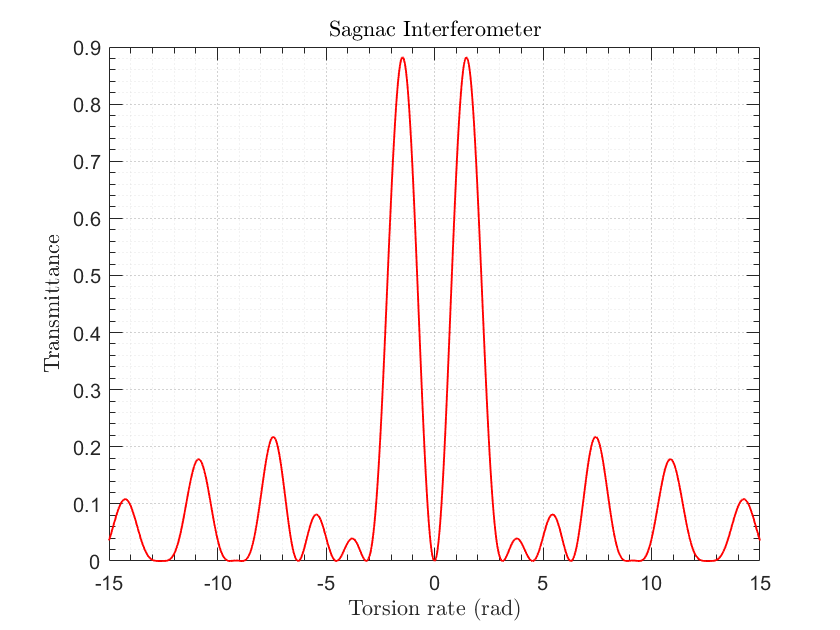

clc
close all

lambda = 1550e-9;       % Wavelength (m)
L_fiber = 1.5;            % Fiber length (m)
alpha = 0.5;            % Coupler rate
Lb = 1;                 % Beat length (m)
Ln = L_fiber / Lb;      % Normalized fiber length
g = 0.16;               % Silica fiber parameter
t = -15:0.01:15;        % Torsion values (rad)
psi0 = 0;               % Fiber main axis rotation angle 
theta = 0;              % Port 3 fiber main axis rotation angle 
DeltaN = lambda / Lb;   % Estimated birefringence  
L1 = 1;                 % Arm length B1
L2 = 1;                 % Arm length B2
t1 = 0;                 % Arm torsion B1
t2 = 0;                 % Arm torsion B2

E1 = [1; 0];           % Input field (Jones vector)
Iin = norm(E1)^2;      % Input intensity

J = zeros(2,2,length(t));
I_out = zeros(1, length(t));

for i = 1:length(t)
    % Compute arm phase delays (constant because t1 and t2 are zero)
    delta_lb1 = (2*pi/lambda) * (L1 * DeltaN);
    delta_c1  = (1 - g/2) * t1;
    
    delta_lb2 = (2*pi/lambda) * (L2 * DeltaN);
    delta_c2  = (1 - g/2) * t2;
    
    % Calculate the arm matrix parameters
    etaB1 = etaBn(delta_lb1, delta_c1);
    etaB2 = etaBn(delta_lb2, delta_c2);
    
    Q1 = Qn(etaB1, delta_c1);
    Q2 = Qn(etaB2, delta_c2);
    
    P1 = Pn(etaB1, delta_lb1);
    P2 = Pn(etaB2, delta_lb2);
    
    B1 = BnMat(P1, Q1);
    B2 = BnMat(P2, Q2);
    
    % Rotation matrices (C1 is constant; C2 includes the t-dependent rotation)
    C1 = C1Mat(theta);
    C2 = C2Mat(psi0, Ln, t(i));
    
    % Compute the loop matrix (FL) – note the correction: the (2,1) element is negative.
    delta_cL = (1 - g/2) * t(i);
    etaFL = etaL(psi0, Ln, delta_cL);
    QFL = QL(psi0, Ln, delta_cL, etaFL);
    PFL = PL(etaFL, Ln);
    FL = FLMat(PFL, QFL);   % Uses the corrected version below
    
    % Total Jones matrix of the system
    J(:,:,i) = B1 * C1 * FL * C2 * B2; 
    
    % Compute the output field using the provided coupler model
    E2 = Eout(E1, J(:,:,i), alpha);
    I_out(i) = norm(E2)^2;
end

T = I_out / Iin;
plot(t, T, 'LineWidth', 0.93, 'Color', [1 0 0]);
xlabel('Torsion rate (rad)', 'Interpreter', 'latex');
ylabel('Transmittance', 'Interpreter', 'latex');
title('Sagnac Interferometer', 'Interpreter', 'latex');
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], 'LineWidth', 0.5);
grid minor
set(gca, 'GridLineStyle', ':', 'GridColor', [0.5, 0.5, 0.5], ...
    'GridAlpha', 0.7, 'MinorGridLineStyle', ':', ...
    'MinorGridColor', [0.8, 0.8, 0.8], 'MinorGridAlpha', 0.5);


%% Function definitions


function C1 = C1Mat(theta)
    % Rotation matrix for the input (port 3)
    C1 = [cos(theta), -sin(theta); sin(theta), cos(theta)];
end

function C2 = C2Mat(psi0, Ln, t)
    % Rotation matrix for the loop; psi0*Ln is a fixed phase offset.
    C2 = [cos(psi0*Ln + t), -sin(psi0*Ln + t); sin(psi0*Ln + t), cos(psi0*Ln + t)];
end

function B = BnMat(P, Q)
    % Arm matrix formed from parameters P and Q.
    B = [P, conj(Q); Q, conj(P)];
end

function P = Pn(etaB, delta_lb)
    % Compute P for the arm matrix.
    P = cos(etaB) - 1j*(delta_lb/2) * (sin(etaB) / etaB);
end

function Q = Qn(etaB, delta_c)
    % Compute Q for the arm matrix.
    Q = delta_c * (sin(etaB) / etaB);
end

function etaB = etaBn(delta_lb, delta_c)
    % Compute the effective phase delay in the arms.
    etaB = sqrt((delta_lb/2)^2 + delta_c^2);
end

function FL = FLMat(P, Q)
    % Loop matrix; note the corrected negative sign in the (2,1) element
    FL = [P, conj(Q); -Q, conj(P)];
end

function P = PL(eta, Ln)
    % Compute the P parameter for the loop matrix.
    P = cos(eta) - pi*1j*Ln * (sin(eta) / eta);
end

function Q = QL(psi0, Ln, delta_c, eta)
    % Compute the Q parameter for the loop matrix.
    Q = (psi0*Ln + delta_c) * (sin(eta) / eta);
end

function eta = etaL(psi0, Ln, delta_c)
    % Compute the effective phase delay in the loop.
    eta = sqrt((pi*Ln)^2 + (psi0*Ln + delta_c)^2);
end

function E2 = Eout(E1, J, alpha)
    % Compute the output field after the coupler.
    % For alpha = 0.5 this essentially takes the sum of the off-diagonal terms.
    Jxx = J(1,1);
    Jxy = J(1,2);
    Jyx = J(2,1);
    E2 = [ (2*alpha-1)*Jxx, (1-alpha)*Jxy + alpha*Jyx;
           -alpha*Jxy - (1-alpha)*Jyx, (1-2*alpha)*Jxx ] * E1;
end
